# WSHP DataCheck MPC

Code for evaluating MPC results, preliminary. Mainly focus on model accuracy.

## 🚀 Initialization and load data

clc;clear all;

% Directory
par_dir = '../';

% data1
filename = 'Atlanta_Shif_TypSum_RB_2004_TypOcc_TypBehav_NoTES_06162023_105632';
data1 = load([par_dir '/real_data/' filename '.mat']);

% data2
filename = 'Atlanta_Shif_TypSum_RB_2004_TypOcc_TypBehav_NoTES_02182024_233452';
data2 = load([par_dir '/sim_data/' filename '.mat']);


## 🧹 Data preprocessing

data1 = data_process(data1);
data2 = data_process(data2);

## 📊 Plot

### [Compare] Zone temperature

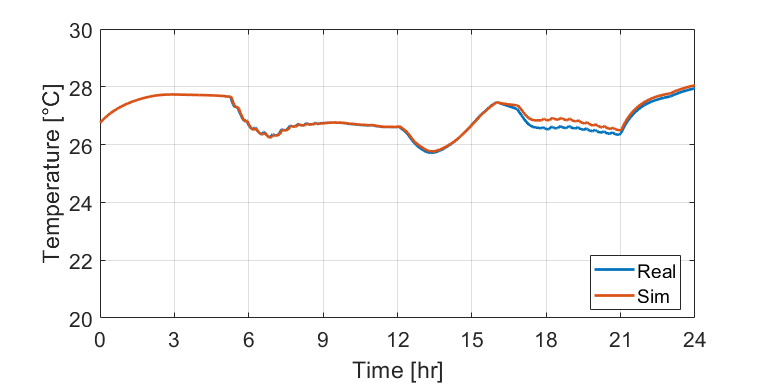

figure('Units', 'inches', 'Position', [0, 0, 8, 4]);
x_label = 'time_step_sim';
y_label = 'zone_temp';
plot(data1.(x_label), data1.(y_label), 'LineWidth', 2); hold on
plot(data2.(x_label), data2.(y_label), 'LineWidth', 2); 
xlim([0 24]);
xticks(0:3:24);
xlabel('Time [hr]');
ylabel('Temperature [°C]');
ylim([20 30])
legend('Real', 'Sim', 'Location', 'best');
grid on;
set(gca, 'FontSize', 16); 

### [Compare] Termostat setpoint

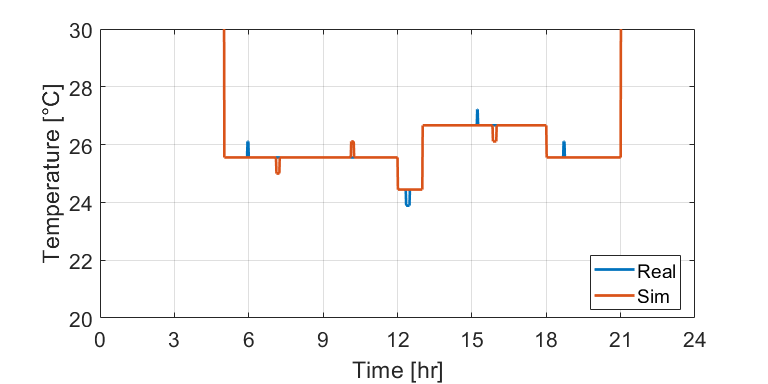

figure('Units', 'inches', 'Position', [0, 0, 8, 4]);
x_label = 'time_step_sim';
y_label = 'tstat_spt';
plot(data1.(x_label), data1.(y_label), 'LineWidth', 2); hold on
plot(data2.(x_label), data2.(y_label), 'LineWidth', 2); 
xlim([0 24]);
xticks(0:3:24);
xlabel('Time [hr]');
ylabel('Temperature [°C]');
ylim([20 30])
legend('Real', 'Sim', 'Location', 'best');
grid on;
set(gca, 'FontSize', 16); 

### [Compare] WSHP power

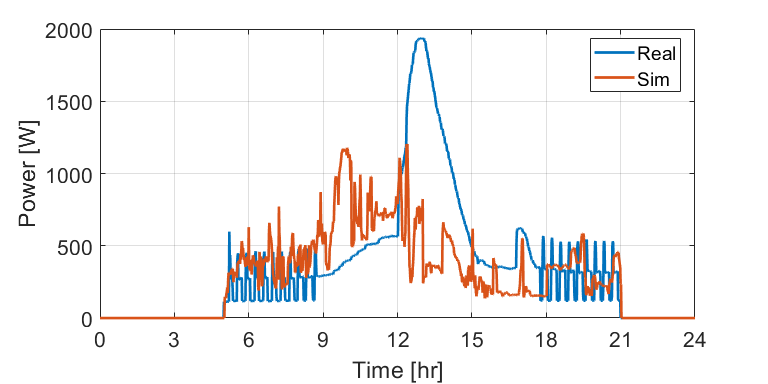

figure('Units', 'inches', 'Position', [0, 0, 8, 4]);
x_label = 'time_step_sim';
y_label = 'wshp_power';
plot(data1.(x_label), data1.(y_label), 'LineWidth', 2); hold on
plot(data2.(x_label), data2.(y_label)*1000, 'LineWidth', 2); 
xlim([0 24]);
xticks(0:3:24);
xlabel('Time [hr]');
ylabel('Power [W]');
legend('Real', 'Sim', 'Location', 'best');
grid on;
set(gca, 'FontSize', 16); 

### [Compare] Mass Flow Rate

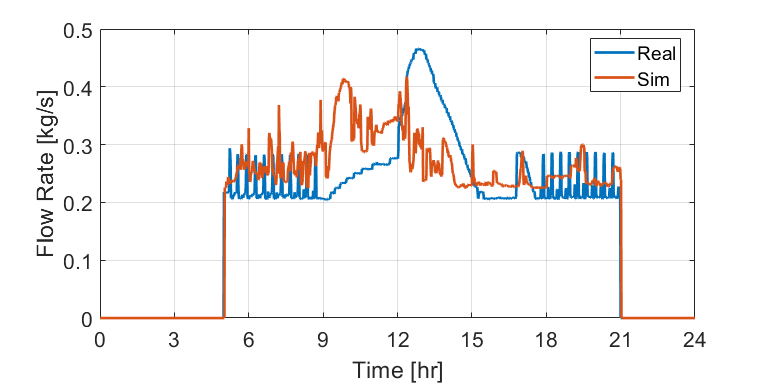

figure('Units', 'inches', 'Position', [0, 0, 8, 4]);
x_label = 'time_step_sim';
y_label = 'sup_flow_rate';
plot(data1.(x_label), data1.(y_label), 'LineWidth', 2); hold on
plot(data2.(x_label), data2.(y_label), 'LineWidth', 2); 
xlim([0 24]);
xticks(0:3:24);
xlabel('Time [hr]');
ylabel('Flow Rate [kg/s]');
legend('Real', 'Sim', 'Location', 'best');
grid on;
set(gca, 'FontSize', 16); 

### [Compare] Supply Air Temperature

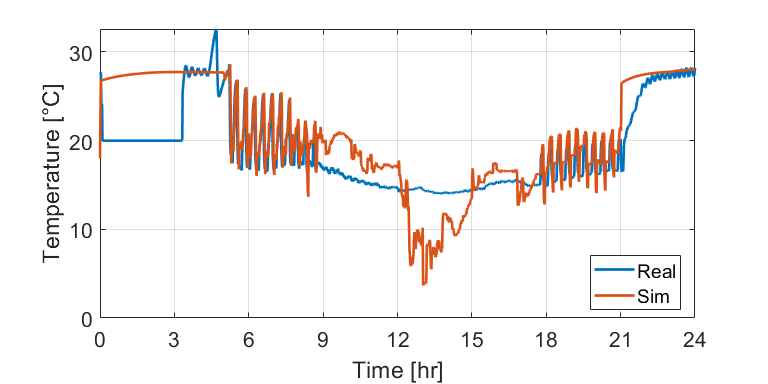

figure('Units', 'inches', 'Position', [0, 0, 8, 4]);
x_label = 'time_step_sim';
y_label = 'sup_temp';
plot(data1.(x_label), data1.(y_label), 'LineWidth', 2); hold on
plot(data2.(x_label), data2.(y_label), 'LineWidth', 2); 
xlim([0 24]);
xticks(0:3:24);
xlabel('Time [hr]');
ylabel('Temperature [°C]');
legend('Real', 'Sim', 'Location', 'best');
grid on;
set(gca, 'FontSize', 16); 

### [Compare] Supply Air Humidity Ratio

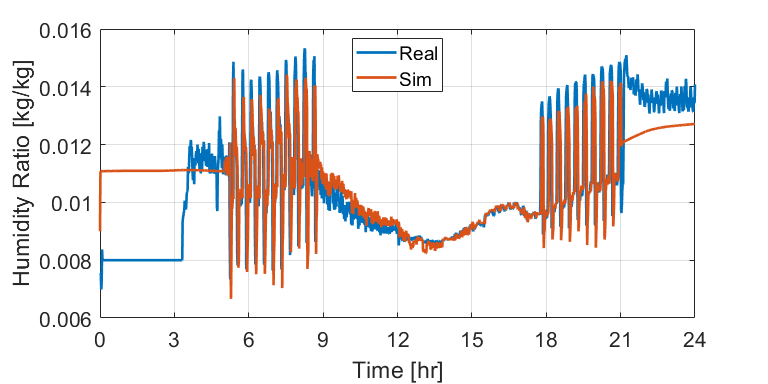

figure('Units', 'inches', 'Position', [0, 0, 8, 4]);
x_label = 'time_step_sim';
y_label = 'sup_humd_ratio';
plot(data1.(x_label), data1.(y_label), 'LineWidth', 2); hold on
plot(data2.(x_label), data2.(y_label), 'LineWidth', 2); 
xlim([0 24]);
xticks(0:3:24);
xlabel('Time [hr]');
ylabel('Humidity Ratio [kg/kg]');
legend('Real', 'Sim', 'Location', 'best');
grid on;
set(gca, 'FontSize', 16); 

### [Compare] Inlet Water Temperature

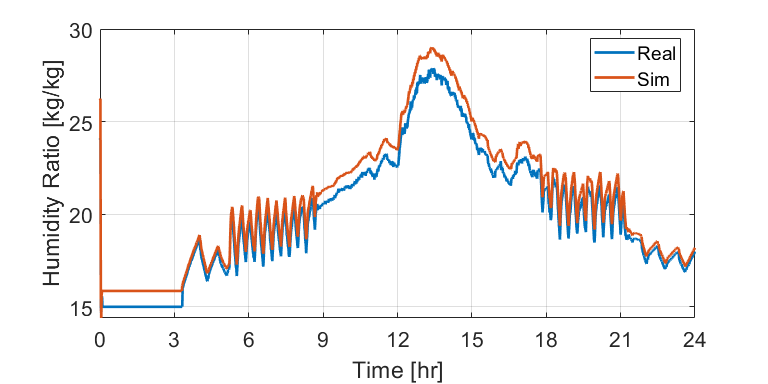

figure('Units', 'inches', 'Position', [0, 0, 8, 4]);
x_label = 'time_step_sim';
y_label = 'inlet_water_temp';
plot(data1.(x_label), data1.(y_label), 'LineWidth', 2); hold on
plot(data2.(x_label), data2.(y_label), 'LineWidth', 2); 
xlim([0 24]);
xticks(0:3:24);
xlabel('Time [hr]');
ylabel('Temperature [C]');
legend('Real', 'Sim', 'Location', 'best');
grid on;
set(gca, 'FontSize', 16); 

### [Compare] Sensible Load

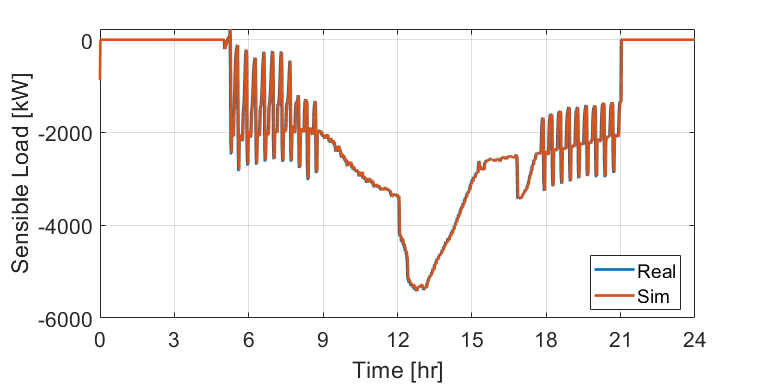

figure('Units', 'inches', 'Position', [0, 0, 8, 4]);
x_label = 'time_step_sim';
y_label = 'sen_load_sim';
plot(data1.(x_label), data1.(y_label), 'LineWidth', 2); hold on
plot(data2.(x_label), data2.(y_label), 'LineWidth', 2); 
xlim([0 24]);
xticks(0:3:24);
xlabel('Time [hr]');
ylabel('Sensible Load [kW]');
legend('Real', 'Sim', 'Location', 'best');
grid on;
set(gca, 'FontSize', 16); 